clc
clf
clear all
close all

# Sample Generator

WARNING: THIS SCRIPT WILL OVERWRITE FILES

Expert data generation for behavioural cloning

generate_data = true;
save_data     = true;

% buffer_name   = 'train100k';
% Nsamples     = 100000;

% buffer_name   = 'train10k';
% Nsamples     = 10000;

buffer_name   = 'validation';
Nsamples      = 1000;

Randomness control

if contains(buffer_name, 'train')
    0
    rng(0)
elseif strcmp(buffer_name, 'validation')
    1
    rng(1)
end

ans = 1

## Parameters

Simulation and control steps

fs_ce = 600;     % Energy control frequency
Ts_ce = 1/fs_ce; % Energy control timestep

## Reference Frame Transforms (RFT)

T = reference_frame_transforms;
RFT        = struct();
RFT.abc2ab = T.abc2ab; % Three-phase to alpha-beta
RFT.ab2abc = T.ab2abc; % Alpha-beta to three-phase
RFT.rot    = T.rot;    % 90° rotation

## Induction Machine (IM)

IM = struct();

Nominal values and structural parameters

Converter control designed to operate with 50% nominal torque and 50% nominal speed

IM.VLLN  = 380;  % [V] Line-line rms rated stator voltage
IM.PN    = 3000; % [W] Rated active power
IM.FPn   = 0.81; % Rated power factor
IM.SN    = IM.PN / IM.FPn; % [VA] Rated apparent power
IM.fN    = 50;             % [Hz] Rated stator frequency
IM.f_max = IM.fN * 0.5;    % [Hz] Max. stator frequency
IM.wN    = 1450 * pi / 30; % [rad/s] Rated rotor speed
IM.w_max = IM.wN * 0.5;    % [rad/s] Max. rotor speed
IM.IN    = IM.SN / (IM.VLLN * sqrt(3)); % [A] Rms rated stator current
IM.TN    = IM.PN / IM.wN;               % [Nm] Rated electrical torque
IM.FrN   = sqrt(2/3) * IM.VLLN / (2 * pi * IM.fN); % [Wb] Rated rotor flux
IM.np    = 2; % Number of pole pairs

Lumped parameters

IM.J    = 0.006;    % [kg/m^2] Rotor inertia
IM.Rs   = 1.8;      % [Ohm] Stator resistance
IM.Rr   = 1.8;      % [Ohm] Equivalent rotor resistance
IM.Los  = 2.6e-3;   % [H] Stator leakage inductance
IM.Lor  = 2.6e-3;   % [H] Rotor leakage inductance
IM.Lm   = 235.1e-3; % [H] Mutual inductance
IM.Ls   = IM.Los + IM.Lm; % [H] Stator inductance
IM.Lr   = IM.Lor + IM.Lm; % [H] Rotor inductance

IM.kr    = IM.Lm / IM.Lr;
IM.ks    = IM.Lm / IM.Ls;
IM.tau_r = IM.Lr / IM.Rr;
IM.o     = 1 - IM.ks * IM.kr;
IM.Ro    = IM.Rs + IM.Rr * IM.kr^2;
IM.Lo    = IM.o * IM.Ls;
IM.tau_o = IM.Lo / IM.Ro;
IM.kT    = 1.5 * IM.np * IM.kr;

IM.isdN  = IM.FrN / IM.Lm;
IM.isqN  = IM.TN / (3/2*IM.np*IM.kr*IM.FrN);

## Modular Multilevel Converter (M2C)

M2C = struct(); % Modular Multilevel Converter parameters

Parameters

M2C.ax     = [1, 1, 1, 0, 0, 0;         % Input incidence matrix
              0, 0, 0, 1, 1, 1];
M2C.ay     = [1, 0, 0, 1, 0, 0;         % Output incidence matrix
              0, 1, 0, 0, 1, 0;
              0, 0, 1, 0, 0, 1];
M2C.p      = size(M2C.ax, 1);           % # of input ports
M2C.q      = size(M2C.ay, 1);           % # of output ports
M2C.A      = [M2C.ax;                   % Incidence matrix
             -M2C.ay];
M2C.m      = size(M2C.A, 2);            % # of clusters
M2C.pinvA  = pinv(M2C.A);               % Incidence matrix inverse
M2C.N      = null(M2C.A, 'rational');   % Nullspace matrix
M2C.n      = size(M2C.N, 2);            % # of LICCs (Linearly Independent Circulating Currents)
M2C.pinvN  = pinv(M2C.N);               % Nullspace matrix inverse
M2C.Rb     = 0.2;                       % [Ohm] Branch resistance
M2C.Lb     = 5e-3;                      % [H] Branch inductance
M2C.Csm    = 987e-6;                    % [F] Submodule capacitance
M2C.Nsm    = 4;                         % # of submodules per cluster
M2C.C      = M2C.Csm / M2C.Nsm;         % [F] Equivalent branch capacitance
M2C.As     = -eye(M2C.m)*M2C.Rb/M2C.Lb; % Cluster current model continuous state matrix
M2C.Bs     = -eye(M2C.m)/M2C.Lb;        % Cluster current model continuous input matrix
M2C.Vdc    = 520;                       % [V] DC-link voltage
M2C.Ax_max = M2C.Vdc / 2;               % Max. input voltage
M2C.Ay_max = sqrt(2/3)*IM.VLLN*IM.w_max/IM.wN + IM.Rs*IM.IN; % Max. output voltage (50% machine's nominal speed)
M2C.ix_max = 4.2;                       % Max. input current
M2C.iy_max = sqrt(IM.isdN^2+(0.5*IM.isqN)^2); % Max. output current
M2C.is_max = 8.5;                       % Max. branch current
M2C.Vc_ref = 520;                       % Cluster capacitor voltage reference
M2C.Ec_ref = M2C.C / 2 * M2C.Vc_ref^2;  % Cluster energy reference
M2C.vc_ref = M2C.Vc_ref / M2C.Nsm;      % Submodule capacitor voltage reference
M2C.vc_dev = 0.15;                      % [pu] Max. capacitor voltage deviation from reference
M2C.vc_m_dev = 0.02;                    % [pu] Max. cap. voltage MEAN deviation from reference

## Cluster Energy Model Predictive Controller (CEMPC)

CEMPC = struct(); % Cluster Energy MPC parameters

CEMPC.Ts        = Ts_ce; % Sampling time
CEMPC.Nl        = 10;    % # of BCD iterations
CEMPC.Np        = 1;     % Rolling horizon length
CEMPC.ONE       = repmat({ones(M2C.m, 1)}, CEMPC.Np, 1);
CEMPC.ONE       = blkdiag(CEMPC.ONE{:});                     % CMV incidence matrix, long horizon
CEMPC.NN        = repmat({M2C.N}, CEMPC.Np, 1);
CEMPC.NN        = blkdiag(CEMPC.NN{:});                      % LICCs incidence matrix, long horizon
CEMPC.MI        = repmat({eye(M2C.m)-ones(M2C.m)/M2C.m}, CEMPC.Np, 1);
CEMPC.MI        = blkdiag(CEMPC.MI{:});                      % Deviation from mean matrix, single step
CEMPC.K         = kron(tril(ones(CEMPC.Np)), eye(M2C.m));
CEMPC.Hu_z      = 2 * CEMPC.NN' * CEMPC.NN / M2C.is_max^2;   % LICCs control effort hessian, normalized
CEMPC.Aineq_z   = [CEMPC.NN; -CEMPC.NN];                     % LICCs control action constraints matrix
CEMPC.Hu_o      = 2 * eye(CEMPC.Np) / M2C.Vc_ref^2;        % CMV control effort hessian, normalized
CEMPC.Aineq_o   = [eye(CEMPC.Np); -eye(CEMPC.Np)];           % CMV control action constraints matrix

CEMPC.lambda_z  = 1e-2; % LICCs control effort weighting factor
CEMPC.lambda_o  = 2e-1; % CMV control effort weighting factor

% CEMPC.lambda_z  = 1e-2 * 10 * 3;
% CEMPC.lambda_o  = 2e-1 * 10 * 1;

## Buffer

p       = M2C.p         % # of input ports

p = 2

q       = M2C.q         % # of output ports

q = 3

m       = M2C.m         % # of clusters

m = 6

n       = M2C.n         % # of circulating currents

n = 2

Ay_max  = M2C.Ay_max;   % Max. output voltage
ix_max  = M2C.ix_max;   % Max. input current
iy_max  = M2C.iy_max;   % Max. output current
is_max  = M2C.is_max;   % Max. cluster current
A       = M2C.A;        % Incidence matrix
pinvA   = M2C.pinvA;    % Incidence matrix inverse
N       = M2C.N;        % Null space matrix
pinvN   = M2C.pinvN;    % Null space matrix inverse
C       = M2C.C;        % Converter equivalent branch capacitance
Vc_ref  = M2C.Vc_ref;   % Cluster capacitor voltage reference
vc_dev  = M2C.vc_dev;   % Max. cluster capacitor voltage deviation
vc_m_dev = M2C.vc_m_dev; % Max. cluster cap. MEAN voltage deviation
Vdc     = M2C.Vdc;      % DC-link voltage
Np      = CEMPC.Np;     % Rolling horizon length
Ts      = Ts_ce;        % Cluster energy control sampling time
Tab2abc = RFT.ab2abc;   % Alpha-beta to three-phase
Tabc2ab = RFT.abc2ab;   % Three-phase to alpha-beta
f_max   = IM.f_max;     % Max. stator frequency

K        = CEMPC.K;
MI       = CEMPC.MI;
NN       = CEMPC.NN;
ONE      = CEMPC.ONE;
Nl       = CEMPC.Nl;
Vc_ref2  = M2C.Vc_ref^2;
Ec_ref   = M2C.Ec_ref;
Ec_ref2  = Ec_ref^2;
Hu_z     = CEMPC.Hu_z;
Aineq_z  = CEMPC.Aineq_z;
lambda_z = CEMPC.lambda_z;
Hu_o     = CEMPC.Hu_o;
Aineq_o  = CEMPC.Aineq_o;
lambda_o = CEMPC.lambda_o;
iA_z     = false(size(zeros(2 * m * Np, 1)));
iA_o     = false(size(zeros(2 * Np, 1)));
options_z                     = mpcActiveSetOptions;
options_z.MaxIterations       = 20;
options_z.ConstraintTolerance = 1e-4;
options_o                     = mpcActiveSetOptions;
options_o.MaxIterations       = 10;
options_o.ConstraintTolerance = 1e-4;

## Inputs

#### Fixed

Ninputs = m + 1;

- Ec-mean(Ec): deviations of cluster capacitor energies from mean (m)

- iP:                   positive terminal DC-link current                              (1)

#### Machine current, voltage and power

Ninputs = Ninputs + 6;

Alpha-beta

- ima, imb:         machine current, alpha-beta                                   (2)

- vma, vmb:       machine voltage, alpha-beta                                   (2)

- pm, qm:           machine instant active and reactive power             (2)

Line variables

- ima, imb:         machine phase currents                                         (2)

- vmac, vmbc:   machine line-line voltages                                      (2)

- p1, p2:            machine instant power (Aron method)                    (2)

#### Optional

% Ninputs = Ninputs + 1;

- wy:                        machine stator frequency                                 (1)

#### Rejected

DC-link voltage is constant, hence DC-link power is proportional to iP. Because of this, vdc and pdc doesn't add information.

Also, the mean energy doesn't impact the intercluster balancing and it isn't affected by the control variables (LICCs and CMV), so it doesn't add information.

Ninputs

Ninputs = 13

## Outputs

Noutputs = n + 1

Noutputs = 3

- ie:  circulating current references       (n)

- vo: common mode voltage reference (1)

## Initialize buffer

Buffer has $N_{\mathrm{samples}}$ samples, with $N_{\textrm{inputs}}$ observations and $N_{\textrm{outputs}}$ actions

buffer   = struct();
buffer.X = zeros(Nsamples, Ninputs);
buffer.Y = zeros(Nsamples, Noutputs);
buffer

buffer = struct with fields:
    X: [1000×13 double]
    Y: [1000×3 double]

Number of active constraints per example

active_constraints_list = zeros(2, Nsamples);

Exit flag to remove unfeasible examples

exitflag_list = zeros(1, Nsamples);

## Generate input data

Create grid of initialization values

Ninit_vals = 1 + m + 6 - 1

Ninit_vals = 12

- Vc_m:    mean cluster capacitor voltages       (1)

- Vc_diff: cluster capacitor voltages deviations (m)

- iP:         positive terminal DC-link current       (1)

- im:         machine current magnitude              (1)

- vm:        machine voltage magnitude              (1)

- gim:       machine current angle                       (1)

- gvm:      machine voltage angle                      (1)

- wy:        machine stator frequency                  (1)*

init_vals = lhsdesign(Nsamples, Ninit_vals)';
size(init_vals)

ans =           12        1000


Select grid variables

VCM0 = ((2*init_vals(1, :)-1)*vc_m_dev + 1) * Vc_ref;          % Vc_ref*[0.98, 1.02]
VCD0 = (2*init_vals(2:m+1, :)-1)*(vc_dev - vc_m_dev) * Vc_ref; % Vc_ref*[-0.13, 0.13]
VC0  = VCM0 + VCD0;                        % Vc_ref*[0.85, 1.15]
IP0  = (2*init_vals(m+2, :)-1) * ix_max;   % ix_max*[-1, 1]
IM0  = init_vals(m+3, :).^(1/2.4)*iy_max;  % iy_max*[0, 1]
VM0  = init_vals(m+4, :).^(1/2.4)*Ay_max;  % Ay_max*[0, 1]
GIM0 = init_vals(m+5, :)*2*pi;             % [0, 2*pi]
GVM0 = init_vals(m+6, :)*2*pi;             % [0, 2*pi]
% WY0  = (2*init_vals(m+7, :)-1)*f_max*2*pi; % wy_max*[-1, 1]
WY0  = 0*init_vals(1, :);

% REVISAR POR QUE LOS ESTADOS NO SON EQUIPROBABLES PROBABLES
% *Por ejemplo el desfase angular entre tensión y corriente (phi)
% tiene cierta característica para la máquina de inducción.
% *En un solo cuadrante P>0 y Q>0. Esto si opera como motor (-pi/2<phi0)
% *En dos cuadrantes Q>0. Esto operando como freno regenerativo (-pi<phi<0)
% Si no tiene doble alimentación Q nunca será negativa.
% *Además, si opero en velocidad de rotor positiva, WY siempre será
% positiva.
% *También, se cumple siempre la característica V/f, es decir, VM es
% proporcional a WY. Podría estimar tensiones cercanas a la curva V/f
% usando esa relación y la caída resistiva, en vez de muestrear VM al azar
% *Otro ejemplo es IP, ya que esta la mayoría del tiempo tendrá signo opuesto a la
% desviación de tensión media VCM (opera por un PI).

% Input/output currents
IX0  = IP0 .* [1; -1];                                % Input currents
IY0  = -RFT.ab2abc * (IM0 .* [cos(GIM0); sin(GIM0)]); % Output currents
IXY0 = [IX0; IY0]; 
IB0  = pinvA * IXY0; % Basic currents

% Input/output voltages
VX0  = Vdc/2 * ones(1, Nsamples) .* [1; -1];         % Input voltages
VY0  = RFT.ab2abc * (VM0 .* [cos(GVM0); sin(GVM0)]); % Output voltages
VXY0 = [VX0; VY0];
VB0  = A' * VXY0;  % Basic voltages

% Max. currents
max(abs(IX0(:)))

ans = 4.1994

max(abs(IY0(:)))

ans = 5.3643

max(abs(IB0(:)))

ans = 3.9950


% Max. voltages
max(VCM0(:))/Vc_ref

ans = 1.0200

min(VCM0(:))/Vc_ref

ans = 0.9800

max(VCD0(:))/Vc_ref

ans = 0.1300

min(VCD0(:))/Vc_ref

ans = -0.1300

max(VC0(:))/Vc_ref-1

ans = 0.1478

min(VC0(:))/Vc_ref-1

ans = -0.1497

max(abs(VX0(:)))

ans = 260

max(abs(VY0(:)))

ans = 165.0855

max(abs(VB0(:)))

ans = 425.0855

## Generate output data

if generate_data

% Initialize progress bar
h = waitbar(0, 'Generating Data...');

tic
for episode = 1:Nsamples

% Sample
Vc   = VC0(:, episode);  % Cluster capacitor voltages
Ec   = 0.5 * C * Vc.^2;  % Cluster capacitor energies
ixy  = IXY0(:, episode); % External currents
vxy  = VXY0(:, episode); % External voltages
wy   = WY0(episode);     % Output frequency

% Predict basic variables
VB = zeros(m, Np);
IB = zeros(m, Np);
if Np > 1
    %%% Input port
    VX = repmat(vxy(1:p), 1, Np-1);
    IX = repmat(ixy(1:p), 1, Np-1);

    %%% Output port
    % Rotation matrix
    angles   = (1:Np-1) * (wy * Ts);
    cos_vals = cos(angles);
    sin_vals = sin(angles);
    ROTy     = reshape([cos_vals; -sin_vals; sin_vals; cos_vals], 2, 2*(Np-1))';

    % Predict
    VY = Tab2abc * reshape(ROTy * Tabc2ab * vxy(p+1:end), 2, Np-1);
    IY = Tab2abc * reshape(ROTy * Tabc2ab * ixy(p+1:end), 2, Np-1);

    %%% Predictions formatting
    
    % Concatenate input/output predictions
    VXY = [VX; VY];
    IXY = [IX; IY];
    
    % Add actual measurement as first predicted step
    VXY = [vxy, VXY];
    IXY = [ixy, IXY];
else
    VXY = vxy;
    IXY = ixy;
end

VB(:) = A' * VXY;
IB(:) = pinvA * IXY;

% Cluster energy MPC

% Preallocation
vo_ref_temp = zeros(Np, 1);
ie_ref_temp = zeros(n*Np, 1);
flag_z = int32(0);
flag_o = int32(0);
vs_temp = zeros(m*Np, 1);
is_temp = zeros(m*Np, 1);

for l = 1:Nl
    %%% LICCs subproblem Jz = Jz_x + Jz_u

    % Initialization
    % vs_temp(:) = VB(:) + ONE * vo_ref_temp;
    vs_temp = VB + vo_ref_temp';
    vs_temp = vs_temp(:);

    % Linear model matrices
    E = Ts * K * diag(vs_temp); % Disturbances matrix
    B = E * NN;                 % Input matrix
    P = IB(:);                  % Disturbances

    % State reference tracking Jx_z, quadratic and linear terms 
    Hx_z = 2 * B' * MI * B / Ec_ref2;
    fx_z = 2 * B' * MI * (repmat(Ec, Np, 1) + E * P) / Ec_ref2;

    % Control action penalization Ju_z, linear term
    fu_z = 2 * NN' * IB(:) / is_max^2;

    % Total cost function J_z
    H_z = Hx_z + lambda_z * Hu_z;
    f_z = fx_z + lambda_z * fu_z;
    
    % Constraints
    ub      =  is_max - IB(:);
    lb      = -is_max - IB(:);
    bineq_z = [ub; -lb];

    % Solve
    [ie_ref_temp, flag_z, iA_z] = mpcActiveSetSolver(H_z, f_z, Aineq_z, bineq_z, zeros(0, n*Np), zeros(0, 1), iA_z, options_z);

    %%% CMV subproblem Jo = Jo_x + Jo_u

    % Initialization
    is_temp = IB(:) + NN * ie_ref_temp;

    % Linear model matrices
    E = Ts * K * diag(is_temp); % Distrubances matrix
    B = E * ONE;                % Input matrix
    P = VB(:);                  % Distrubances

    % State reference tracking Jx_o, quadratic and linear terms 
    Hx_o = 2 * B' * MI * B / Ec_ref2;
    fx_o = 2 * B' * MI * (repmat(Ec, Np, 1) + E * P) / Ec_ref2;

    % Control action penalization Jo_u
    fu_o = zeros(Np, 1) / Vc_ref2;

    % Total cost function J_o
    H_o = Hx_o + lambda_o * Hu_o;
    f_o = fx_o + lambda_o * fu_o;

    % Constraints
    ub = min([Vc(1:3); 0; 0; 0] - VB, [], 1)';
    lb = max([0; 0; 0; -Vc(4:6)] - VB, [], 1)';
    bineq_o = [ub; -lb];

    % Solve
    [vo_ref_temp, flag_o, iA_o] = mpcActiveSetSolver(H_o, f_o, Aineq_o, bineq_o, zeros(0, Np), zeros(0, 1), iA_o, options_o);
end

% ie_ref = ie_ref_temp(1:n);
ie_ref = ie_ref_temp(1:2);
vo_ref = vo_ref_temp(1);

if and(0 < flag_z, 0 < flag_o)
    flag = 1;
else
    flag = 0;
end

% Add to buffer
iP     = ixy(1);
im_abc = -ixy(p+1:end);
vm_abc = vxy(p+1:end);
im_ab  = Tabc2ab * im_abc;
vm_ab  = Tabc2ab * vm_abc;
pm     = 3/2 * (vm_ab(1) * im_ab(1) + vm_ab(2) * im_ab(2));
qm     = 3/2 * (vm_ab(2) * im_ab(1) - vm_ab(1) * im_ab(2));
sm     = [pm; qm];
p1     = (vm_abc(1) - vm_abc(3)) * im_abc(1);
p2     = (vm_abc(2) - vm_abc(3)) * im_abc(2);
p12    = [p1; p2];

% OBSERVATION
% Fixed variables
buffer.X(episode, 1:m)     = Ec - mean(Ec);
buffer.X(episode, m+1)     = iP;

% Machine alpha-beta variables
buffer.X(episode, m+2:m+3) = im_ab;
buffer.X(episode, m+4:m+5) = vm_ab;
buffer.X(episode, m+6:m+7) = sm;

% % Machine line variables
% buffer.X(episode, m+2:m+3) = im_abc(1:2);
% buffer.X(episode, m+4:m+5) = vm_abc(1:2) - vm_abc(3);
% buffer.X(episode, m+6:m+7) = p12;

% % Optional variable
% buffer.X(episode, m+8)     = wy;

% CONTROL ACTION
buffer.Y(episode, 1:n)     = ie_ref;
buffer.Y(episode, end)     = vo_ref;

% Controller status
exitflag_list(episode)              = flag;
active_constraints_list(1, episode) = sum(iA_z);
active_constraints_list(2, episode) = sum(iA_o);

% Update progress bar
waitbar(episode/Nsamples, h, sprintf('Generating Data: %d%%', round((episode/Nsamples)*100)));
end
toc

% Close progress bar
close(h)

end

Elapsed time is 3.233061 seconds.


Filter non feasible examples

mask     = exitflag_list == 1;
buffer.X = buffer.X(mask, :)

buffer = struct with fields:
    X: [1000×13 double]
    Y: [1000×3 double]

buffer.Y = buffer.Y(mask, :)

buffer = struct with fields:
    X: [1000×13 double]
    Y: [1000×3 double]

Count active constraints

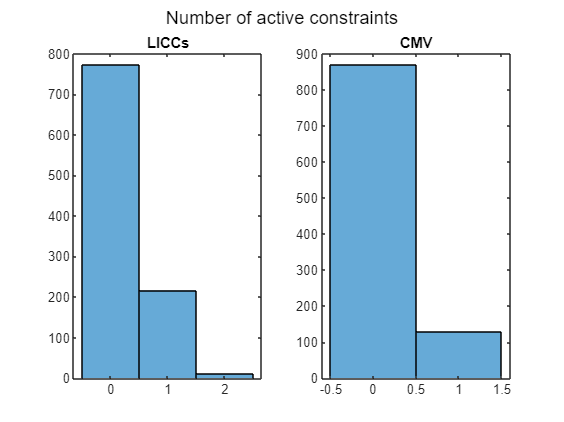

figure
subplot(1, 2, 1)
histogram(active_constraints_list(1, :))
title('LICCs')
subplot(1, 2, 2)
histogram(active_constraints_list(2, :))
title('CMV')
sgtitle('Number of active constraints')

Save generated data

buffer.X = buffer.X';
buffer.Y = buffer.Y';

if save_data
    save(strcat('ImitationLearningSimulink\TrainingData\Data\', buffer_name, '.mat'), 'buffer')
end